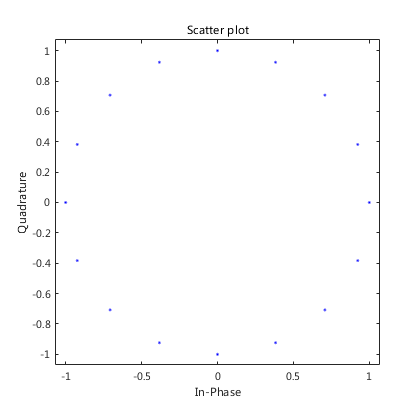

M = 16;
x = 0:M-1;
scatterplot(pskmod(x,M));

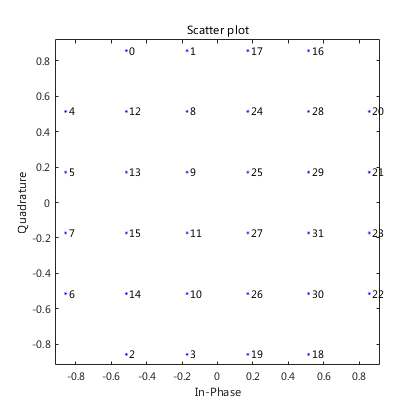

M = 32;
x = 0:M-1;
y = qammod(x,M);
scale = modnorm(y,'peakpow',1);
y = scale* y;
scatterplot(y);
hold on;
for i = 1:length(y)
    text(real(y(i)),imag(y(i)),[' ' num2str(i-1)]);
end

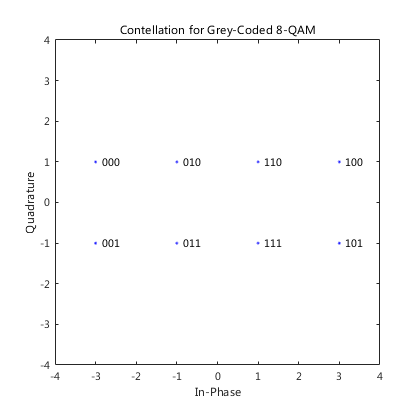

M = 8;
x = 0:M-1;
y = qammod(x,M,'gray');
scatterplot(y,1,0,'b.');
hold on;
annot = dec2bin([0:length(y)-1], log2(M));
text(real(y)+0.15,imag(y),annot);
axis([-4 4 -4 4]);
title('Contellation for Grey-Coded 8-QAM');

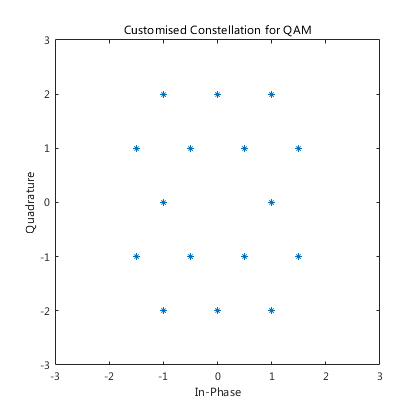

inphase = [1/2 -1/2 1 0 3/2 -3/2 1 -1];
quadr = [1 1 0 2 1 1 2 2];
inphase = [inphase; -inphase]; inphase = inphase(:);
quadr = [quadr; -quadr]; quadr = quadr(:);
const = inphase + 1j*quadr;

scatterplot(const, 1, 0, '*');
hold on;
axis([-3 3 -3 3]);
title('Customised Constellation for QAM');